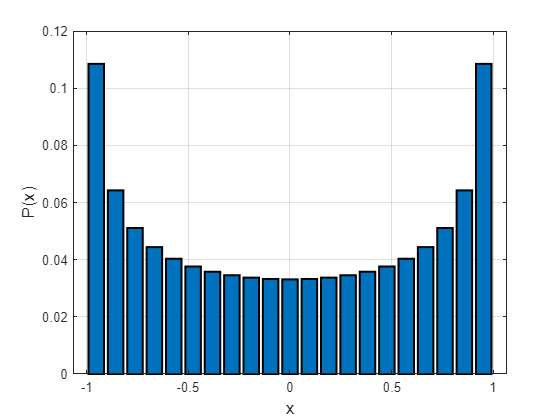

% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear


% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 2; %the ratio amax/(xmax-xmin)

xmax = 1;
N = 21; % Total number of bins in [-xmax,xmax]
x_bin_size = 2*xmax/N;
x_grid = linspace(-xmax+x_bin_size/2,xmax-x_bin_size/2,N);

% We assign a distribution to X\in x_grid
% In the write-up, this is the data distribution

% % Gaussian distribution
% sigma = 0.1;% 
% shift = 0.6;
% x_P = exp(-(x_grid-shift).^2/2/sigma^2)+exp(-(x_grid+shift).^2/2/sigma^2);

% % Exponential distribution
% lambda = 6; 
% x_P = 1/lambda*exp(-lambda*x_grid); 

% Beta distribution
a=0.5*ones(size(x_grid));
b=0.5*ones(size(x_grid));
x_P = betapdf((x_grid+xmax)/2,a,b);

x_P = x_P./ sum(x_P);

figure
bar(x_grid,x_P,LineWidth=1.5);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on


% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = exp(linspace(log(0.5),log(8),20));

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
VarOptWorst = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [varVector,pMatrix,a_grid] =... 
        opt_variance(eps_grid(i),delta,r,axRatio,x_grid,x_P);
    VarOpt(i) = x_P*varVector;
    VarOptWorst(i) = max(varVector);
end

--------------------------------
eps = 0.500000, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 0.578555, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 0.669452, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 0.774630, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 0.896332, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 1.037155, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 1.200103, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 1.388651, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 1.606822, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 1.859271, delta = 0.000000

Optimal solution found.

--------------------------------
eps = 2.151381, delta = 0.000000

Optimal solut

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end

% The variance vector of Duchi mechanism
VarDuchi = zeros(1,length(eps_grid));
VarDuchiWorst = zeros(1,length(eps_grid));
var_duchi = @(ti,eps) ((exp(eps)+1)/(exp(eps)-1)).^2 - ti.^2;
for i = 1:length(eps_grid)
    temp = var_duchi(x_grid,eps_grid(i));
    VarDuchi(i) = temp *x_P';
    VarDuchiWorst(i) = max(temp);
end

% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
VarPiecewiseWorst = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    temp = var_piecewise(x_grid,eps_grid(i));
    VarPiecewise(i) = temp *x_P';
    VarPiecewiseWorst(i) = max(temp);
end

% The variance vector of Hybrid mechanism
VarHybrid = zeros(1,length(eps_grid));
VarHybridWorst = zeros(1,length(eps_grid));
alpha = @(eps) sign(max(eps-0.61,0))*(1-exp(-eps/2));
var_hybrid = @(ti,eps) alpha(eps)*var_piecewise(ti,eps) + (1-alpha(eps))*var_duchi(ti,eps);
for i = 1:length(eps_grid)
    temp = var_hybrid(x_grid,eps_grid(i));
    VarHybrid(i) = temp *x_P';
    VarHybridWorst(i) = max(temp);
end


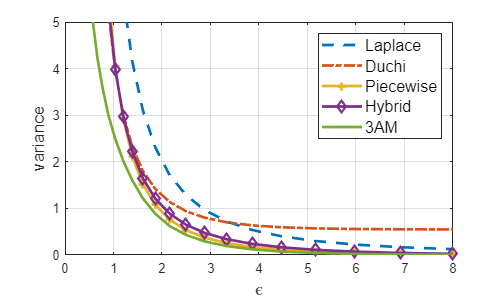

% The plots
figure;
f = figure;
f.Position = [0 0 500 300];

plot(eps_grid,VarLaplace,'--',LineWidth=2);
hold on
plot(eps_grid,VarDuchi,'-.',LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,'-+',LineWidth=2);
hold on
plot(eps_grid,VarHybrid,'-D',LineWidth=2);
% hold on
plot(eps_grid,VarOpt,LineWidth=2);
ylim([0,5])
% title("Average Variance Comparison",FontSize=13)
xlabel("\epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace", "Duchi",...
    "Piecewise","Hybrid","3AM",FontSize=12)
grid on

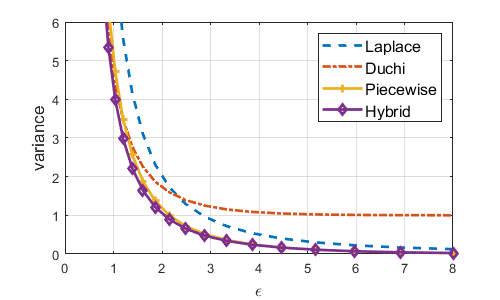

figure;
f = figure;
f.Position = [0 0 500 300];
plot(eps_grid,VarLaplace,'--',LineWidth=2);
hold on
plot(eps_grid,VarDuchiWorst,'-.',LineWidth=2);
hold on
plot(eps_grid,VarPiecewiseWorst,'-+',LineWidth=2);
hold on
plot(eps_grid,VarHybridWorst,'-D',LineWidth=2);
hold on
% plot(eps_grid,VarOptWorst,LineWidth=2);
ylim([0,6])
% title("Worst Variance Comparison",FontSize=13)
xlabel("\epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace", "Duchi",...
    "Piecewise","Hybrid",FontSize=12)
grid on